% Read image
clc
clear

N = 16;

for i = 1:N
    if (i < 10)
        number = '0' + string(i);
    else
        number = string(i);
    end
    
    name = './DB1/db1_' + number + '.jpg';
    
    RGB = imread(name);
    
    croppedImage = faceDetection(RGB);
    
    grayImage = im2gray(croppedImage);
    
    image_vector(:,i) = grayImage(:);
     
end

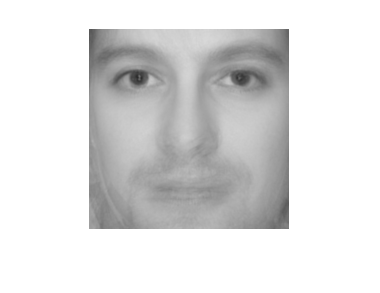

% Mean-face
meanFace = sum(image_vector,2)/N;
meanFaceImage = reshape(meanFace, 200, 200)/255;
imshow(meanFaceImage);


% Subtract mean
A = im2double(image_vector)-(meanFace/255);

% Covariance 
% C = AA';
C1 = A'*A;

[V, D] = eig(C1);

u = A*V

u =     0.0000   -0.2178   -0.1412    0.0842   -0.0358    0.0168    0.0381    0.1729   -0.4037   -0.1202   -0.0741   -0.1771   -0.0175   -0.2960   -0.3135    0.2450
    0.0000   -0.1931   -0.1111    0.0707   -0.0807   -0.0207    0.0604    0.1807   -0.4260   -0.1643   -0.0831   -0.1496    0.0221   -0.2762   -0.2853    0.2665
    0.0000   -0.2050   -0.1131    0.0647   -0.0860   -0.0232    0.0646    0.1579   -0.4380   -0.1445   -0.1160   -0.1793    0.0394   -0.2804   -0.2730    0.2532
    0.0000   -0.1983   -0.1029    0.0863   -0.1092   -0.0305    0.0850    0.1499   -0.4407   -0.1252   -0.1452   -0.1840    0.0591   -0.2915   -0.2571    0.2979
    0.0000   -0.2051   -0.1195    0.0567   -0.0920    0.0271    0.1089    0.1362   -0.4058   -0.1358   -0.1447   -0.1874    0.0667   -0.3042   -0.2754    0.2830
    0.0000   -0.2190   -0.1227    0.0166   -0.0935    0.0504    0.1219    0.1264   -0.3664   -0.1270   -0.1524   -0.1983    0.0752   -0.2777   -0.3072    0.2468
    0.0000   -0.2423   -0.1463


values = max(u)

values =     0.0000    0.5428    0.3975    0.4735    0.4928    0.4440    0.6216    0.4631    0.4426    0.3949    0.4074    0.6037    0.5866    0.4079    0.5861    0.7710


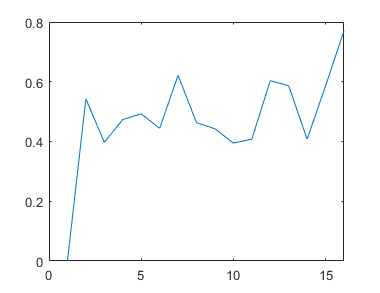


plot(values)

function croppedImage = faceDetection(RGB)
    % White balance
    rgbImageWhite = cWhitePatch(RGB);
    
    % Face mask
    mask = faceMask(rgbImageWhite);
    % disp('Face mask'), imshow(mask);
    
    % Eye map
    map = eyeMap(rgbImageWhite);
    % disp('Eye map'), imshow(eyeMap);
    
    % Combine
    res = map & mask;
    % disp('Eye map + face mask'), imshow(res);
    
    % Cleaning
    res = cleaning(res);
    
    % Get eye coordinates
    [lab,num]=bwlabel(res);
    stats = regionprops(lab);
    eye1 = getfield(stats,{1},'Centroid');
    y1 = eye1(1);
    x1 = eye1(2);
    eye2 = getfield(stats,{2},'Centroid');
    y2 = eye2(1);
    x2 = eye2(2);
    
    % Rotate the images based on the eyes
    rotatedImage = rotate_image(RGB,y1,x1,y2,x2);
    % disp('Rotated image'), imshow(rotatedImage);
    
    % Get new eye coordinates
    map = rotate_image(res,y1,x1,y2,x2);
    [lab,num]=bwlabel(map);
    stats2 = regionprops(lab);
    eye1 = getfield(stats2,{1},'Centroid');
    eye2 = getfield(stats2,{2},'Centroid');
    x1 = eye1(1);
    y1 = eye1(2);
    x2 = eye2(1);
    y2 = eye2(2);
    
    % Crop the image square for eigenfaces
    croppedImage = crop(rotatedImage, x1, y1, x2, y2);
end